Load slinky data from `Fhdata.mat`, then load the data into

[force, height] = dataprep(MJ1);

mass in g

m = 47.72;
m = m/1000;
g = 9.80665;

initial collapsed length $h_0$ in cm

h0 = 2.992;
h0 = h0/100;

dimensions $d_1$ and $d_2$ in mm

d1 = 0.39;
d2 = 0.93;
d1 = d1/1000;
d2 = d2/1000;
R1 = 35.85/200;
R2 = 39.59/200;

density $\rho$ in g/cm^3

rho = 3.36;
rho = rho*1000;

number of turns $N$

N = 76;
N = N - 1;          % end correction

mean radius $\langle R \rangle$ in cm

R = 1.89;
R= R/100;

calculate $2\pi\langle R \rangle$

circ = 2*pi*R

circ = 0.1188

calculate $2\pi\langle R \rangle N$

lenprim = circ*N

lenprim = 8.9064

length $h$ in cm

h = [30 40 50 60 70 80 90 100 110 120 130]';
h = (h-0.873)/100;  % end correction

Calculate $L_0$ 

L0 = vertlen(N,R,h0)

L0 = 8.9065

Lw = vertlen(N,R,h(1))

Lw = 8.9128

Calculate $L$

L = horzlen(N,R,h)

L =     8.9112
    8.9150
    8.9200
    8.9260
    8.9332
    8.9415
    8.9509
    8.9614
    8.9730
    8.9857


Calculate length vector from height

lengths = vertlen(N, R, height);

Calculate extension vector from height

extension = lengths - L0

extension =     0.0132
    0.0203
    0.0216
    0.0230
    0.0245
    0.0262
    0.0277
    0.0296
    0.0314
    0.0330


Stress-strain curve fitting

stress = force/(d1*d2);
strain = (lengths-L0)/L0;

Youngfit = fit(strain,stress,'Exp2')

Youngfit =      General model Exp2:
     Youngfit(x) = a*exp(b*x) + c*exp(d*x)
     Coefficients (with 95% confidence bounds):
       a =   2.137e+09  (-1.235e+17, 1.235e+17)
       b =       117.1  (-6.562e+05, 6.565e+05)
       c =  -2.136e+09  (-1.235e+17, 1.235e+17)
       d =       117.1  (-6.565e+05, 6.567e+05)

Young's modulus $E$

hplot = linspace(min(h),max(h),1000)';
Lplot = horzlen(N,R,hplot)

Lplot =     8.9112
    8.9112
    8.9112
    8.9113
    8.9113
    8.9113
    8.9114
    8.9114
    8.9114
    8.9115


expstrain = (Lplot - L0)./L0;
E = Youngfit(expstrain)./expstrain;

Calculate speed $c$

c = sqrt(E/rho);
rgy = sqrt((d2)/3)

rgy = 0.0176

Calculate $\alpha$

alpha = Lplot ./ (8*pi.*c.*rgy).^0.5

alpha =     0.4639
    0.4647
    0.4655
    0.4662
    0.4670
    0.4678
    0.4685
    0.4693
    0.4701
    0.4708


Consolidate data from `Spectrogram.mlx`

alphaexpt = [0.628
0.6356
0.6376
0.6403
0.6836
0.7005
0.7214
0.7674
0.7954
0.8155
0.8567]

beta =     0.6280
    0.6356
    0.6376
    0.6403
    0.6836
    0.7005
    0.7214
    0.7674
    0.7954
    0.8155


Plot summary curve

cexp = (L ./ alphaexpt).^2 ./ (8*pi.*rgy)

cexp =   455.0196
  444.5849
  442.2908
  439.1653
  385.9130
  368.1996
  347.9047
  308.1685
  287.5977
  274.3710


Erev = rho*(cexp.^2)

Erev = 	1.0e+08 *

    6.9566
    6.6412
    6.5729
    6.4803
    5.0040
    4.5552
    4.0669
    3.1909
    2.7791
    2.5294


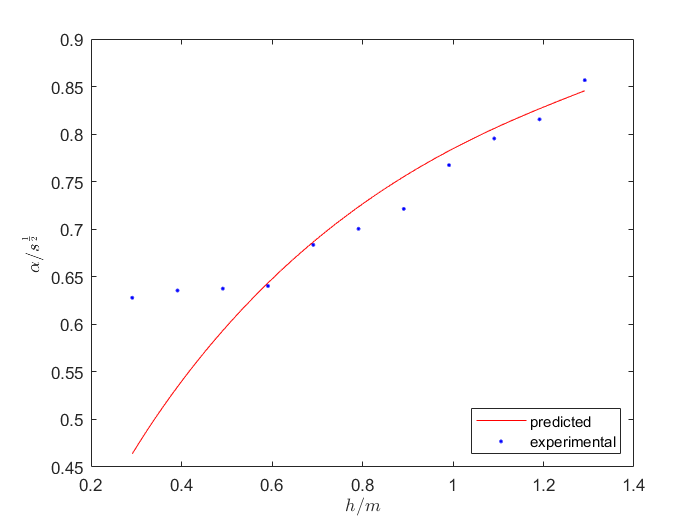

XF = 0


plot(hplot, alpha, 'r-', h, alphaexpt, 'b.')
legend({'predicted','experimental'}, 'Location','southeast')

xlabel('$h / m$','Interpreter','latex')
ylabel('$\alpha / s^{\frac12}$','Interpreter','latex')